# UAVのホバリング Part 3: ゲインチューニング

## PID制御器のゲインチューニング

これまで示してきたように、PID制御のパラメータは、基本的に比例ゲイン、積分ゲイン、微分ゲインとなる。制御器の計算則を決定した後、所望の応答性を実現し、かつ安定性を保つように、それらのフィードバックゲインをチューニングする必要がある。PIDゲインのチューニングは、経験に基づく手作業による方法から、ステップ応答法や限界感度法のような実験やシミュレーション結果を利用しある規則に基づいて決定する方法、あるいは、自動チューニングまで様々な方法がある。

限界感度法はいくつかのモデルで有用であるが、今回のUAVのモデルには適用できないため、本節では、経験的調整法を紹介する。また、周波数応答推定を活用した自動調整器ブロック「PID Autotuner」についても紹介する。

## 経験的調整法

基本的には、[Part 1](matlab:open('UHG_control_UAV_p1.mlx'))、[Part 2](matlab:open('UHG_control_UAV_p2.mlx'))で説明した事柄を踏まえて調整していけばよい。

制御の目標は、ひとまず「指令値との誤差を可能な限り少なくする」とする。

「UHG_PID_control_4.slx」を開き、モデルを確認する。

model_name = 'UHG_PID_control_4';
open_system(model_name);

モデルを実行し、応答を確認する。

% ゲインを設定
P_gain = 0;  % 左の編集フィールドの数値を変えると自動的に実行される
I_gain = 0;  % 左の編集フィールドの数値を変えると自動的に実行される
D_gain = 0;  % 左の編集フィールドの数値を変えると自動的に実行される

sim(model_name);
UHG_PID_control_4_plot_in_SDI;

全てのゲインが0であるため当然であるが、UAVは落下し続ける結果となる。ゲインが0ということは、制御を全く行わないことを意味する。このように、最初は全てのゲインを0として調整を開始する。

以降のセクションでゲイン調整の指示があった時、上記コマンドの編集フィールドの数値を変更することで、簡単に結果を確認できる。

### 1.Pゲインを上げていく

Pゲインを上げていき、ある程度の応答性能が出るところまでゲイン上昇と実行結果の確認を繰り返す。

最初は「指数的」に上げていくこと。例えば、とりあえずPゲインを1して実行してみる。この時、結果はそれほど変化していないように見える。次にゲインを10として実行する。そうすると、positionは約12秒時に-45m地点で一定となることがわかる。目標値まではまだまだゲインを上げなければならないので、さらにゲインを100として実行する。結果、程よく指令値に近づき、commandも一時的に飽和限界を超える動作をする。

Iゲイン、Dゲインを最初に調整しないこと。[Part 1](matlab:open('UHG_control_UAV_p1.mlx'))で説明した通り、積分器、微分器はあくまで比例器の補助である。

### 2. Iゲインを上げていく

積分器は、指令値との偏差を無くすために用いる。偏差が無視できない大きさである場合、Iゲインを上げていき、ある程度の応答性能が出るところまでゲイン上昇と実行結果の確認を繰り返す。

Pゲインと同じく、「指数的」に上げていくこと。同じように100とした場合は発散してしまうので、このような場合は10に戻り、20、50と刻み幅を小さくして上げていくこと。

Iゲインを上げていくと、必然的に振動的な応答となる。偏差をなくすことと安定化させることはトレードオフである。

commandが制御器の飽和限界を超えることがある場合は、[アンチワインドアップ](matlab:open('AWU_anti_windup.mlx'))を適用すると、安定を保ちつつ、さらにゲインを上げることができる。必要であれば適用すること。

### PゲインとIゲインの関係性

PゲインとIゲインは独立していない。例えば、Pゲインを10、Iゲインを10としてみると、モデルは発散してしまう。このように、ゲイン同士の比率によっても発散するかどうかが変わるため、手作業のゲイン調整は難しいのである。

実験計画の面で重用なのは、**複数のゲインを同時に変えて実行しない**ことである。必ず1個のゲインだけを変えて実行すること。

### 3. Dゲインを上げていく

微分器は、振動を抑制するために用いる。偏差抑制のために必要なIゲインが定まった後、振動が無視できない場合にDゲインを上げていき、ある程度の応答性能が出るところまでゲイン上昇と実行結果の確認を繰り返す。

微分器はノイズに弱いため、ゲインを上げる際には、常にcommandの高周波振動（リプル）の振幅に注意を払うこと。リプルがcommandの上下限値を超えるような場合は、フィルターを導入すること。

フィルターのカットオフ周波数を下げていくと、微分器の応答の位相が比例器、積分器に対して遅れていく。そのため、応答が振動的になる場合がある。

### PゲインとDゲインの関係性

UAVのように積分器を含むプラントモデルの場合、Dゲインを上げると、応答を安定させたままPゲインをさらに上げることができる。このとき、ゲイン同士の比率によっても発散するかどうかが変わるため、1個ずつ調整すること。

この用途で微分器を活用することは、制御設計の現場でよく行われており、PI-D制御など、様々なPID制御の応用型が提案されている。

## PID Autotuner

Simulink Control Design™のライブラリに「Closed-Loop PID Autotuner」というブロックがある。これを用いると、PIDのゲインを自動でチューニングすることができる。

「Closed-Loop PID Autotuner」は、PID制御器の操作量に一定時間擾乱を加え、その応答を解析することで、プラントモデルの周波数応答を推定する。その応答からゲインを算出する。

ここでは、「Closed-Loop PID Autotuner」を用いたチューニング手法を紹介する。

「UHG_PID_control_5.slx」を開き、モデルを確認する。

model_name = 'UHG_PID_control_5';
open_system(model_name);

「Closed-Loop PID Autotuner」は、PID制御器の出力を入力し、それに擾乱を加えたものを出力する。プラントモデルの応答をフィードバックし、ポート「y」に入力する。ポート「start/stop」には、擾乱を加える（推定する）かどうかのフラグを指定する。

また、今回制御モデルは「離散時間」で設計している。「Closed-Loop PID Autotuner」は、ゲインの推定アルゴリズムをコード生成し、マイコンなどに実装することができる。従って、基本的には「離散時間」に設定する必要がある。

モデルを実行し、応答を確認する。

set_param([model_name, '/start_stop_signal'], 'ActiveScenario', 'No_op');
sim(model_name);
UHG_PID_control_4_plot_in_SDI;

ゲインは「PID Controller」ブロックに外部から入力している。デフォルトではPゲインを100、I、Dゲインを0としている。

### 「Closed-Loop PID Autotuner」の設定について

応答の目標値として「調整」タブの「ターゲットの帯域幅(ラジアン/秒)」と「ターゲットの位相余裕(度)」、擾乱の大きさとして「実験」タブの「正弦波振幅」を設定する。

ターゲットの帯域幅を$w$とすると、ステップ応答の立ち上がり時間は$0\ldotp 7\pi /w$[s]となると考えてよい。ターゲットの位相余裕が大きいほど減衰的に、小さいほど振動的になる。例えば、位相余裕を変えるとFig.1のように応答が変化する。

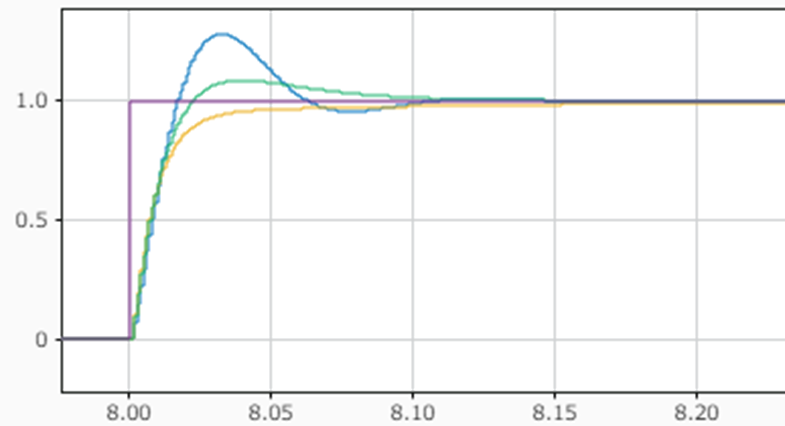

Fig.1 応答波形

ここで、青線、緑線、黄線はそれぞれターゲットの位相余裕を30、60、90に設定したときの応答波形である。

実験の持続時間（摂動を与える時間）は、なるべく$200/w$[s]以上とすること。この時間は、ポート「start/stop」に入力する信号のオン時間の長さによって調整する。

「正弦波振幅」は以下の条件を満たすように設定しなければならない。

- 摂動がプラント アクチュエータのすべての不感帯を克服してノイズ レベルを超える応答を生成できる程度に大きい

- 定格操作点近傍のほぼ線形の領域内でプラントを実行し続け、プラントの入力または出力の飽和を回避できる程度に小さい

実験では正弦波信号が重ね合わせられる。その振動の最大振幅は、「正弦波振幅」の最大3～6倍の大きさとなる。取り得る最大摂動がプラント アクチュエータの範囲内に必ず収まるようにすること。アクチュエータが飽和状態になると、推定周波数応答に誤りが発生することがある。

今回は、「ターゲットの帯域幅(ラジアン/秒)」を2、ターゲットの位相余裕(度)」を60、「正弦波振幅」を200とした。よって、実験の持続時間は100[s]となる。

チューニングを実行する。「start_stop_signal」ブロックのアクティブなシナリオを「Tuning」に切り替えて実行する。

set_param([model_name, '/start_stop_signal'], 'ActiveScenario', 'Tuning');
sim(model_name);
UHG_PID_control_4_plot_in_SDI;

摂動が加えられ、その結果、「pid gains」ポートからPID制御ゲインが算出されている。

算出したゲインは、予め「tuned_gains」ブロックに入力している。ここで、「gain_switch」を切り替え、調整後のゲインで実行した動作を確認する。

open_system([model_name, '/gain_switch']);
set_param([model_name, '/start_stop_signal'], 'ActiveScenario', 'No_op');
sim(model_name);
UHG_PID_control_4_plot_in_SDI;

調整時にはノイズやアクチュエータの飽和の影響を加味できないことに注意すること。調整後のゲインでは、commandはノイズの影響を受けて大きく振動し、その振幅は上下限値を超えている。

[（Part 2: 積分器、微分器の拡張）戻る](matlab:(proceed_live_page('UHG_control_UAV_p2.mlx')))　|　[進む（離散化とマイコン実装について）](matlab:(proceed_live_page('DSD_discrete_and_deployment.mlx')))

*Copyright 2021 The MathWorks, Inc.*